# APS1022 Project

## Part a

## Load data


data = readtable('monthly_prices_dec_to_june.csv');
dates = data{:,1};
prices = data{:,2:end};
returns = diff(log(prices));  % log returns

## Estimate parameters

mu = mean(returns);             % monthly mean return
Q = cov(returns);               % monthly covariance matrix
mu_annual = mu * 12;
Q_annual = Q * 12;

## Obtain risk free rate

% Retrieve the actual U.S. risk-free rate for June 2011,
% using the 3‑month Treasury Bill rate from FRED, which is
% a standard proxy in portfolio analysis.
c = fred;
data = fetch(c, 'TB3MS', '06/01/2011', '06/30/2011');  % 3-month T-bill
rf = data.Data(end,2) / 100;  % convert % to decimal

## Compute market mean return using shares and prices data from yfinance

% We assume 20 stocks is the market. Since yfinance doesn't provide historical market caps
% directly, we estimate it by using formula market cap = shares outstanding * close price,
% where shares and close price are downloaded from yfinance.

% We will use latest shares outstanding with June 2011 prices (given that float doesn't
% change much month-to-month) because yfinance only gives current shares outstanding.

T = readtable('price_and_shares_2011.csv');

prices = T.Price_2011_06_30;
shares = T.Shares_Outstanding;
tickers = T.Ticker;

% Compute Market Capitalizations and Weights
market_caps = prices .* shares;
weights_mktcap = market_caps / sum(market_caps);

r_mkt_series = returns * weights_mktcap;  % full time series of market return
mean_mkt = mean(r_mkt_series) * 12;       % annualized mean
var_mkt = var(r_mkt_series) * 12;         % annualized variance

lambda_idzorek = (mean_mkt - rf) / var_mkt;
fprintf('lambda = %.4f\n', lambda_idzorek);

lambda = 0.9588


## Construct MVO

% Assume:
% - mu_annual: 1×n vector of annualized expected returns
% - Q_annual:  n×n annualized covariance matrix
% - lambda_idzorek: scalar
% - n = number of assets
n = length(mu_annual);

% Define MVO objective function
mvo_obj = @(x) lambda_idzorek * (x' * Q_annual * x) - mu_annual * x;

% Constraints
Aeq = ones(1, n);
beq = 1;
lb = [];
ub = [];
x0 = ones(n,1)/n;

% fmincon solver
opts = optimoptions('fmincon','Display','none','Algorithm','sqp');
[x_mvo, fval] = fmincon(mvo_obj, x0, [], [], Aeq, beq, lb, ub, [], opts);

% Display weights
disp('MVO Portfolio Weights:')

MVO Portfolio Weights:


disp(array2table(x_mvo', 'VariableNames', tickers'))

      F         CAT       DIS        MCD        KO        PEP        WMT         C         WFC        JPM        AAPL      IBM        PFE         JNJ       XOM        COP         ED          T        VZ        NEM  
    ______    _______    ______    _______    _______    ______    ________    ______    _______    ________    ______    ______    ________    _______    ______    _______


% Convert weights into table
x_mvo_table = array2table(x_mvo, 'VariableNames', {'MVO Portfolio Weights'}, 'RowNames', tickers);
disp(x_mvo_table)

            MVO Portfolio Weights
            _____________________

    F               1.2787       
    CAT            -2.3102       
    DIS             6.2093       
    MCD            -2.6341       
    KO             0.26781       
    PEP             7.7859       
    WMT           0.064815       
    C               0.1239       
    WFC            -5.5249       
    JPM           -0.27272       
    AAPL            2.5689       
    IBM             10.703       
    PFE           -0.21225       
    JNJ            -7.0389       
    XOM             1.0108       
    COP            -7.9527       
    ED            -0.83034       
    T        

## Construct robust MVO with CI = 90%

T_obs = size(returns, 1);            % Number of time periods (e.g., 43 months)
alpha = 0.90;                        % 90% confidence level
epsilon = sqrt(chi2inv(alpha, n));  % sqrt of chi-squared critical value

Theta = diag(diag(Q_annual)) / T_obs;

% Set Up Optimization Problem
robust_obj_90 = @(x) lambda_idzorek * (x' * Q_annual * x) ...
                 - mu_annual * x ...
                 + epsilon * norm(sqrtm(Theta) * x, 2);

% Define Constraints
Aeq = ones(1, n);     % sum(x) = 1
beq = 1;
lb = [];     % x >= 0
ub = [];              % no upper bound
x0 = ones(n, 1) / n;  % initial guess: equal weights

% Solve Using fmincon
opts = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');

[x_robust_90, fval] = fmincon(robust_obj_90, x0, [], [], Aeq, beq, lb, ub, [], opts);

% Display weights
disp('Robust MVO Weights (ellipsoidal, 90%):')

Robust MVO Weights (ellipsoidal, 90%):


disp(array2table(x_robust_90', 'VariableNames', tickers'))

       F         CAT         DIS       MCD        KO        PEP        WMT         C         WFC         JPM        AAPL       IBM         PFE         JNJ        XOM         COP          ED          T         VZ         NEM   
    _______    ________    _______    ______    ______    _______    _______    _______    ________    ________    _______    ______    _________    _______    ________    


% Convert weights into table
x_robust90_table = array2table(x_robust_90, 'VariableNames', {'Robust MVO Weights (ellipsoidal, 90%)'}, 'RowNames', tickers);
disp(x_robust90_table)

            Robust MVO Weights (ellipsoidal, 90%)
            _____________________________________

    F                       0.21046              
    CAT                    -0.48048              
    DIS                     0.47218              
    MCD                      -0.281              
    KO                       0.1399              
    PEP                     0.83847              
    WMT                     0.11128              
    C                       0.83594              
    WFC                    -0.64041              
    JPM                    -0.14037              
    AAPL                    0.14656              
    IBM                      2.3092              
    PFE                   -0.076363         

## Construct robust MVO with CI = 95%

T_obs = size(returns, 1);            % Number of time periods (e.g., 43 months)
alpha = 0.95;                        % 95% confidence level
epsilon = sqrt(chi2inv(alpha, n));  % sqrt of chi-squared critical value

Theta = diag(diag(Q_annual)) / T_obs;

% Set Up Optimization Problem
robust_obj_95 = @(x) lambda_idzorek * (x' * Q_annual * x) ...
                 - mu_annual * x ...
                 + epsilon * norm(sqrtm(Theta) * x, 2);

% Define Constraints
Aeq = ones(1, n);     % sum(x) = 1
beq = 1;
lb = [];     % x >= 0
ub = [];              % no upper bound
x0 = ones(n, 1) / n;  % initial guess: equal weights

% Solve Using fmincon
opts = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');

[x_robust_95, fval] = fmincon(robust_obj_95, x0, [], [], Aeq, beq, lb, ub, [], opts);

% Display weights
disp('Robust MVO Weights (ellipsoidal, 95%):')

Robust MVO Weights (ellipsoidal, 95%):


disp(array2table(x_robust_95', 'VariableNames', tickers'))

      F         CAT         DIS        MCD         KO         PEP        WMT          C         WFC         JPM        AAPL       IBM         PFE         JNJ         XOM         COP          ED          T          VZ         NEM   
    ______    ________    _______    ________    _______    _______    ________    _______    ________    ________    _______    ______    _________    ________    ________ 


% Convert weights into table
x_robust95_table = array2table(x_robust_95, 'VariableNames', {'Robust MVO Weights (ellipsoidal, 95%)'}, 'RowNames', tickers);
disp(x_robust95_table)

            Robust MVO Weights (ellipsoidal, 95%)
            _____________________________________

    F                        0.1869              
    CAT                    -0.41518              
    DIS                     0.37303              
    MCD                    -0.24307              
    KO                      0.12842              
    PEP                     0.71352              
    WMT                    0.097129              
    C                       0.76853              
    WFC                    -0.50911              
    JPM                    -0.11898              
    AAPL                    0.12869              
    IBM                      1.9892              
    PFE                   -0.061326         

## Construct Risk Parity Portfolio

% define objective function

% Q_annual: covariance matrix (n×n)
n = size(Q_annual, 1);

% Objective function: sum of squared deviations from θ
risk_parity_obj = @(z) sum((z(1:n) .* (Q_annual * z(1:n)) - z(end)).^2);

% set constraints
Aeq = [ones(1, n), 0];     % sum(x) = 1
beq = 1;
lb = [zeros(n, 1); -Inf];  % x ≥ 0, θ unrestricted
ub = [];                   % no upper bound
x0 = [ones(n, 1)/n; 0.01]; % initial guess for [x; θ]

% solve Using fmincon
opts = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');

[z_opt, fval] = fmincon(risk_parity_obj, x0, [], [], Aeq, beq, lb, ub, [], opts);
x_risk_parity = z_opt(1:n);    % extract weights

% display portfolio weights
disp('Risk Parity Portfolio Weights:')

Risk Parity Portfolio Weights:


disp(array2table(x_risk_parity', 'VariableNames', tickers'))

       F          CAT         DIS         MCD          KO         PEP        WMT          C          WFC         JPM         AAPL        IBM         PFE        JNJ         XOM         COP          ED          T           VZ         NEM   
    ________    ________    ________    ________    ________    _______    ________    ________    ________    ________    ________    ________    _______    ________    _____


% Convert weights into table
x_rp_table = array2table(x_risk_parity, 'VariableNames', {'Risk Parity Portfolio Weights'}, 'RowNames', tickers);
disp(x_rp_table)

            Risk Parity Portfolio Weights
            _____________________________

    F                 0.036936           
    CAT               0.013179           
    DIS               0.020277           
    MCD               0.030853           
    KO                0.036434           
    PEP                0.10024           
    WMT               0.016082           
    C                 0.061993           
    WFC               0.058343           
    JPM               0.034072           
    AAPL              0.054386           
    IBM               0.070394           
    PFE                0.05557           
    JNJ               0.059023           
    XOM               0.050083        

## Construct a portfolio where weights are based on market capitalizations

% the weights are already computed above in the section of
% computing market mean return.
% Convert weights into table
x_mkt_table = array2table(weights_mktcap, 'VariableNames', {'Market Cap Portfolio Weights'}, 'RowNames', tickers);
disp(x_mkt_table)

            Market Cap Portfolio Weights
            ____________________________

    F                 0.023085          
    CAT                0.02146          
    DIS               0.030081          
    MCD               0.025841          
    KO                0.062069          
    PEP               0.041388          
    WMT               0.060743          
    C                 0.033334          
    WFC               0.039137          
    JPM               0.048765          
    AAPL              0.076743          
    IBM               0.065331          
    PFE               0.047626          
    JNJ               0.068599          
    XOM                0.15032          
    C

## Compute metrics for each portfolios using July data

% load file
P = readtable('monthly_prices_july.csv');
P.Date = datetime(P.Date);  % convert string to datetime

% extract prices
price_0630 = P{P.Date == datetime(2011,7,1), 2:end};  % June 30 prices
price_0731 = P{P.Date == datetime(2011,8,1), 2:end};  % July 29/30 prices

% compute july log returns
r_july = log(price_0731 ./ price_0630)';  % returns as column vector (n×1)

% obtain rf again
% Retrieve the actual U.S. risk-free rate for July 2011,
% using the 3‑month Treasury Bill rate from FRED, which is
% a standard proxy in portfolio analysis.
c = fred;
rf_data = fetch(c, 'TB3MS', '07/01/2011', '07/31/2011');  % 3-month T-bill
rf_july = rf_data.Data(end, 2) / 100;  % convert % to decimal

% define a function to evaluate portfolios
function [ret, var_, std_, sharpe] = eval_portfolio(w, r, rf, Q)
    ret = w' * r;
    var_ = w' * Q * w;
    std_ = sqrt(var_);
    if std_ > 0
        sharpe = (ret - rf) / std_;
    else
        sharpe = NaN;
    end
end

% evaluate portfolios
[ret_mvo, var_mvo, std_mvo, sr_mvo] = eval_portfolio(x_mvo, r_july, rf_july, Q_annual);
[ret_rob90, var_rob90, std_rob90, sr_rob90] = eval_portfolio(x_robust_90, r_july, rf_july, Q_annual);
[ret_rob95, var_rob95, std_rob95, sr_rob95] = eval_portfolio(x_robust_95, r_july, rf_july, Q_annual);
[ret_rp,  var_rp,  std_rp,  sr_rp ] = eval_portfolio(x_risk_parity, r_july, rf_july, Q_annual);
[ret_mkt, var_mkt, std_mkt, sr_mkt] = eval_portfolio(weights_mktcap, r_july, rf_july, Q_annual);

% display results
strategy_names = {'MVO', 'Robust MVO 90%', 'Robust MVO 95%', 'Risk Parity', 'Market Cap'};
results = table(strategy_names', ...
    [ret_mvo; ret_rob90; ret_rob95; ret_rp; ret_mkt], ...
    [var_mvo; var_rob90; var_rob95; var_rp; var_mkt], ...
    [std_mvo; std_rob90; std_rob95; std_rp; std_mkt], ...
    [sr_mvo; sr_rob90; sr_rob95; sr_rp; sr_mkt], ...
    'VariableNames', {'Strategy', 'Return', 'Var', 'StdDev', 'SharpeRatio'});

disp('Portfolio Evaluation for July 2011:')

Portfolio Evaluation for July 2011:


disp(results)

         Strategy           Return        Var       StdDev     SharpeRatio
    __________________    __________    ________    _______    ___________

    {'MVO'           }        1.3445      2.3241     1.5245       0.88167 
    {'Robust MVO 90%'}       0.21134     0.12179    0.34899       0.60443 
    {'Robust MVO 95%'}       0.18236    0.095128    0.30843       0.58996 
    {'Risk Parity'   }    -0.0042342      0.0266    0.16309     -0.028414 
    {'Market Cap'    }     -0.020456    0.045596    0.21353      -0.09767 



%

## Part b

## Load data (Jan 2011 to Nov 2011)

prices = readtable('monthly_prices_jan_to_nov.csv');  % must include dates from Jan 2011 to Dec 2011
T = readtable('price_and_shares_2011.csv');
prices.Date = datetime(prices.Date);            % ensure datetime format

## Rolling window loop

test_months = 7:11;  % July to November
results = [];
c = fred;   % Create FRED connection once
prev_rf = 0.0004;  % Default in case of missing data

for m = test_months
    % Define estimation window: previous 6 months
    start_idx = m - 6;
    end_idx = m - 1;

    % Get estimation window log returns
    price_window = prices{start_idx:end_idx, 2:end};  % exclude date column
    log_returns = diff(log(price_window));            % (5 x 20)

    mu = mean(log_returns);      % monthly mean return
    Q = cov(log_returns);        % monthly covariance
    mu_annual = mu * 12;
    Q_annual = Q * 12;

    % Market cap weights for this month
    % Use price at end of estimation window (i.e., end of month m - 1)
    price_latest = prices{end_idx, 2:end};           % 1×20 row vector
    shares = T.Shares_Outstanding;                   % 20×1 vector
    market_caps = price_latest .* shares';           % 1×20 .* 1×20 (element-wise)
    weights_mktcap = market_caps / sum(market_caps); % normalize to sum to 1

    % Market return and variance
    r_mkt_series = log_returns * weights_mktcap';
    mean_mkt = mean(r_mkt_series) * 12;
    var_mkt = var(r_mkt_series) * 12;

    % Get risk-free rate for month m-1
    estimation_date = datestr(prices.Date(end_idx), 'mm/dd/yyyy');  % e.g., '06/30/2011'
    start_rf = datestr(prices.Date(end_idx - 1), 'mm/dd/yyyy');
    end_rf = datestr(prices.Date(end_idx), 'mm/dd/yyyy');
    rf_data = fetch(c, 'TB3MS', start_rf, end_rf);

    if isempty(rf_data.Data)
        warning('Missing FRED data for %s. Using previous rate.', estimation_date);
        if m > 7
            rf = prev_rf;
        else
            rf = 0.0004;  % fallback if July has no data
        end
    else
        rf = rf_data.Data(end, 2) / 100;  % convert % to decimal
        prev_rf = rf;
    end
    
    % compute lambda
    lambda_idzorek = (mean_mkt - rf) / var_mkt;

    % === Solve all 4 portfolios using previous code blocks ===

    % 1. MVO --> x_mvo
    % Assume:
    % - mu_annual: 1×n vector of annualized expected returns
    % - Q_annual:  n×n annualized covariance matrix
    % - lambda_idzorek: scalar
    % - n = number of assets

    n = length(mu_annual);
    e = ones(n, 1);
    mu_vec = mu_annual';

    % Define MVO objective function
    mvo_obj = @(x) lambda_idzorek * (x' * Q_annual * x) - mu_annual * x;
    
    % Constraints
    Aeq = ones(1, n);
    beq = 1;
    lb = zeros(n,1);
    ub = [];
    x0 = ones(n,1)/n;
    
    % fmincon solver
    opts = optimoptions('fmincon','Display','off','Algorithm','sqp');
    [x_mvo, fval] = fmincon(mvo_obj, x0, [], [], Aeq, beq, lb, ub, [], opts);

    % 2. Robust MVO with CI=90% --> x_robust_90
    T_obs = size(log_returns, 1);            % Number of time periods (e.g., 43 months)
    alpha = 0.90;                        % 90% confidence level
    epsilon_rob90 = sqrt(chi2inv(alpha, n));  % sqrt of chi-squared critical value

    Theta = diag(diag(Q_annual)) / T_obs;

    % Set Up Optimization Problem
    robust_obj_90 = @(x) lambda_idzorek * (x' * Q_annual * x) ...
                     - mu_annual * x ...
                     + epsilon_rob90 * norm(sqrtm(Theta) * x, 2);

    % Define Constraints
    Aeq = ones(1, n);     % sum(x) = 1
    beq = 1;
    lb = zeros(n, 1);     % x >= 0
    ub = [];              % no upper bound
    x0 = ones(n, 1) / n;  % initial guess: equal weights

    % Solve Using fmincon
    opts = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');

    [x_robust_90, fval] = fmincon(robust_obj_90, x0, [], [], Aeq, beq, lb, ub, [], opts);

    % 3. Robust MVO with CI=95% --> x_robust_95
    alpha = 0.95;                        % 95% confidence level
    epsilon_rob95 = sqrt(chi2inv(alpha, n));  % sqrt of chi-squared critical value

    Theta = diag(diag(Q_annual)) / T_obs;

    % Set Up Optimization Problem
    robust_obj_95 = @(x) lambda_idzorek * (x' * Q_annual * x) ...
                     - mu_annual * x ...
                     + epsilon_rob95 * norm(sqrtm(Theta) * x, 2);
    % Solve Using fmincon
    [x_robust_95, fval] = fmincon(robust_obj_95, x0, [], [], Aeq, beq, lb, ub, [], opts);

    % 4. Risk Parity --> x_risk_parity
    % define objective function

    % Q_annual: covariance matrix (n×n)
    n = size(Q_annual, 1);

    % Objective function: sum of squared deviations from θ
    risk_parity_obj = @(z) sum((z(1:n) .* (Q_annual * z(1:n)) - z(end)).^2);

    % set constraints
    Aeq_rp = [ones(1, n), 0];     % sum(x) = 1
    beq_rp = 1;
    lb_rp = [zeros(n, 1); -Inf];  % x ≥ 0, θ unrestricted
    ub_rp = [];                   % no upper bound
    x0_rp = [ones(n, 1)/n; 0.01]; % initial guess for [x; θ]

    % solve Using fmincon
    [z_opt, fval] = fmincon(risk_parity_obj, x0_rp, [], [], Aeq_rp, beq_rp, lb_rp, ub_rp, [], opts);
    x_risk_parity = z_opt(1:n);    % extract weights

    % 5. Market Cap --> weights_mktcap
    % the weights are already computed above
    weights_mktcap = weights_mktcap';

    % ==== Evaluate on next month ====
    price_start = prices{m, 2:end};
    price_end = prices{m+1, 2:end};
    r_test = log(price_end ./ price_start)';

    % Store performance
    [r1, v1, s1, sh1] = eval_portfolio(x_mvo, r_test, rf, Q_annual);
    [r2, v2, s2, sh2] = eval_portfolio(x_robust_90, r_test, rf, Q_annual);
    [r3, v3, s3, sh3] = eval_portfolio(x_robust_95, r_test, rf, Q_annual);
    [r4, v4, s4, sh4] = eval_portfolio(x_risk_parity, r_test, rf, Q_annual);
    [r5, v5, s5, sh5] = eval_portfolio(weights_mktcap, r_test, rf, Q_annual);

    results = [results;
        r1, v1, s1, sh1;
        r2, v2, s2, sh2;
        r3, v3, s3, sh3;
        r4, v4, s4, sh4;
        r5, v5, s5, sh5];

end

## Display results

methods = repmat(["MVO"; "Robust MVO 90% CI"; "Robust MVO 95% CI"; "Risk Parity"; "Market Cap"], 5, 1);
months = repelem(["July", "August", "September", "October", "November"]', 5);

T_result = array2table(results, ...
    'VariableNames', {'Return', 'Variance', 'StdDev', 'Sharpe'});
T_result.Method = methods;
T_result.Month = months;

T_result = movevars(T_result, {'Month', 'Method'}, 'Before', 'Return');
format shortG
disp(T_result)

       Month             Method             Return        Variance      StdDev      Sharpe  
    ___________    ___________________    ___________    __________    ________    _________

    "July"         "MVO"                     0.026428     0.0004283    0.020695       1.2577
    "July"         "Robust MVO 90% CI"       0.030605    0.00020532    0.014329       2.1079
    "July"         "Robust MVO 95% CI"       0.030588    0.00020231    0.014223       2.1224
    "July"         "Risk Parity"          -0.00030617     0.0010824    0.032899    -0.021465
    "July"         "Market Cap"             -0.011711     0.0056892    0.075427     -0.16056
    "August"       "MVO"                    -0.022324     0.0015681      0.0396     -0.57385
    "August"       "Robust MVO 90% CI"      -0.0187

## Part c

## Extract returns and Sharpe ratios

% Extract monthly returns (reshape to 5 portfolios x 5 months)
returns = reshape(results(:,1), [5, 5]);     % 5 portfolios × 5 months (July–Nov)
stds    = reshape(results(:,3), [5, 5]);     % corresponding StdDevs

% Compute cumulative wealth over June–Nov
% Start from June 30 prices → apply July return first
W0 = ones(5, 1);                % Initial wealth = 1 for all portfolios
wealth = zeros(5, 6);          
wealth(:,1) = W0;

for t = 1:5
    wealth(:,t+1) = wealth(:,t) .* (1 + returns(:,t));  % recursively multiply
end

% Compute Sharpe ratios
sharpe = returns ./ stds;

## Plot cumulative wealth

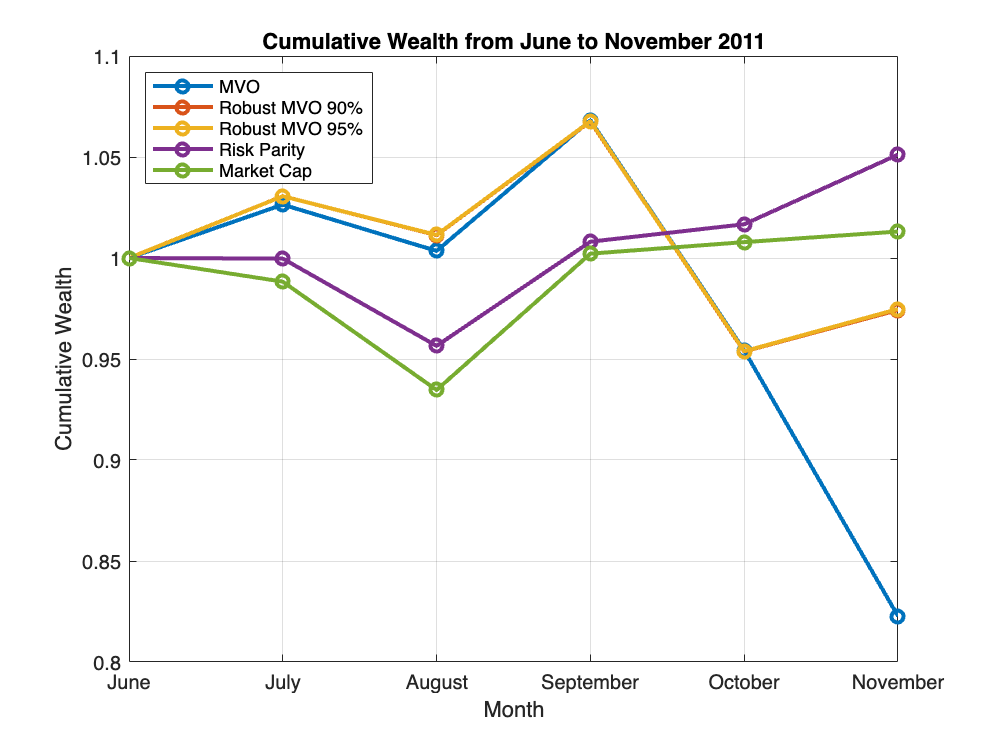

% Plot cumulative wealth from June to November 
months = ["June", "July", "August", "September", "October", "November"];
methods = ["MVO", "Robust MVO 90%", "Robust MVO 95%", "Risk Parity", "Market Cap"];

plot(wealth', '-o', 'LineWidth', 2)
legend(methods, 'Location', 'northwest')
xlabel('Month')
ylabel('Cumulative Wealth')
xticks(1:6)
xticklabels(months)
title('Cumulative Wealth from June to November 2011')
grid on

## Plot Sharpe ratios

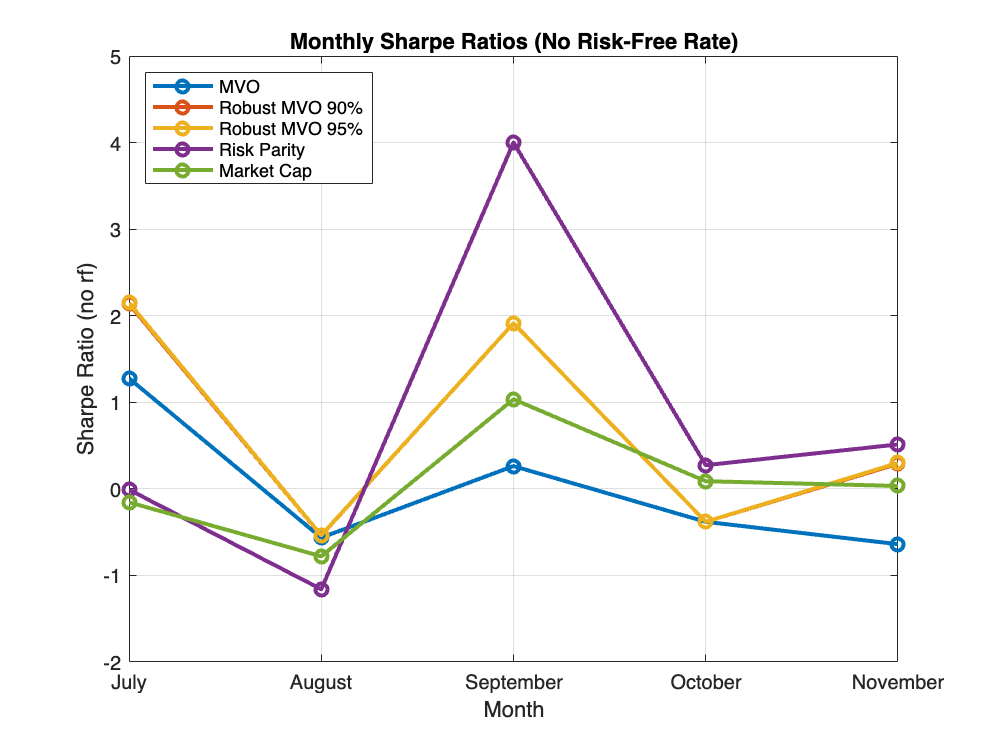

plot(sharpe', '-o', 'LineWidth', 2)
legend(methods, 'Location', 'northwest')
xlabel('Month')
ylabel('Sharpe Ratio (no rf)')
xticks(1:5)
xticklabels(["July", "August", "September", "October", "November"])
title('Monthly Sharpe Ratios (No Risk-Free Rate)')
grid on